# Euler Method

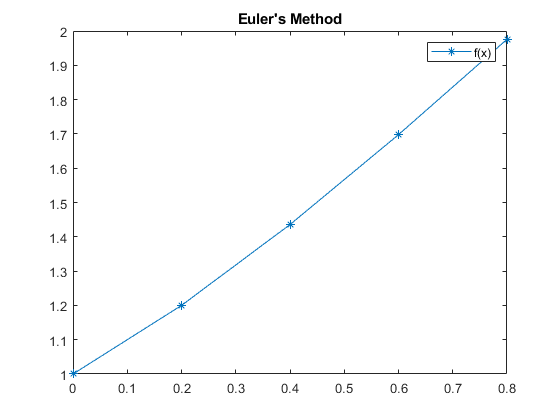

y0 = 1;
x0 = 0;
xn = 0.8;
h = 0.2;
f = @(x, y) cos(x) + sin(x);

[x, y] = euler_method(x0, xn, y0, h, f);

x

x =          0    0.2000    0.4000    0.6000    0.8000


y

y =     1.0000    1.2000    1.4357    1.6978    1.9758


# Runge Kutta 4th Order

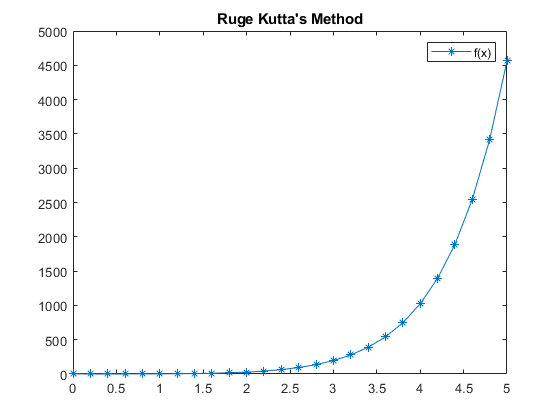

y0 = 1;
x0 = 0;
xn = 5;
h = 0.2;
f = @(x, y) 3*x^2*exp(x)-y;

[x, y] = rk4_method(x0, xn, y0, h, f);

x

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000


y

y = 	1.0e+03 *

    0.0010    0.0008    0.0007    0.0008    0.0012    0.0021    0.0038    0.0065    0.0109    0.0176    0.0277    0.0425    0.0638    0.0941    0.1367    0.1959    0.2775    0.3893    0.5413    0.7470    1.0238    1.3945    1.8889    2.5459    3.4158    4.5638


# Heat Equation

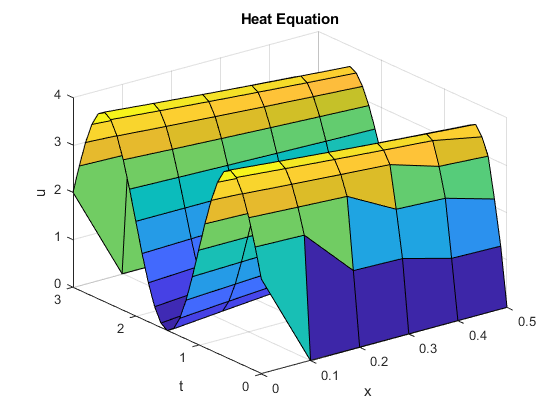

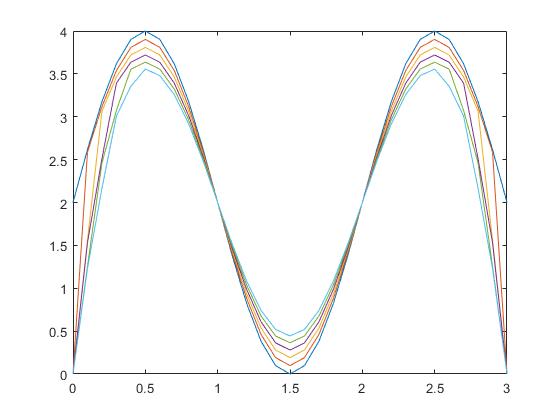

c = sqrt(1/20);
x0 = 0;
xn = 3;
t0 = 0;
tn = 0.5;
h = 0.1;
k = 0.1;
f = @(x) 2 * (1+sin(pi*x));

u = heat_equation(x0, xn, t0, tn, h, k, c, f);

u

u =     2.0000         0         0         0         0         0
    2.6180    2.5878    1.5590    1.5317    1.2556    1.2309
    3.1756    3.1180    3.0633    2.5113    2.4618    2.1647
    3.6180    3.5388    3.4635    3.3919    3.0738    3.0090
    3.9021    3.8090    3.7205    3.6363    3.5562    3.3550
    4.0000    3.9021    3.8090    3.7205    3.6363    3.5562
    3.9021    3.8090    3.7205    3.6363    3.5562    3.4800
    3.6180    3.5388    3.4635    3.3919    3.3238    3.2590
    3.1756    3.1180    3.0633    3.0113    2.9618    2.9147
    2.6180    2.5878    2.5590    2.5317    2.5056    2.4809


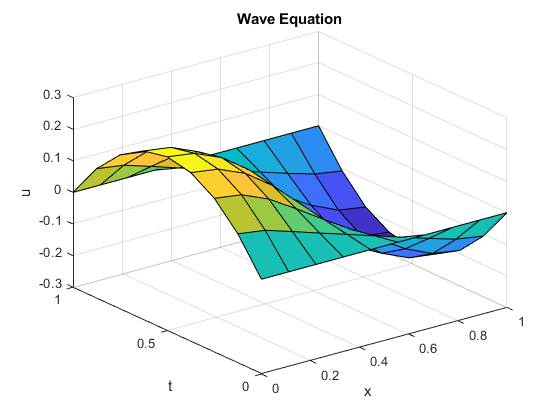

c = sqrt(1);
x0 = 0;
xn = 1;
t0 = 0;
tn = 1;
h = 1/8;
k = 1/9;
f = @(x) x.*(1-x);
g = @(x) 0;

u = wave_equation(x0, xn, t0, tn, h, k, c, f, g);

u

u =          0         0         0         0         0         0         0         0         0         0
    0.1094    0.0970    0.0697    0.0414    0.0141   -0.0139   -0.0417   -0.0694   -0.0949   -0.1085
    0.1875    0.1752    0.1381    0.0841    0.0273   -0.0276   -0.0832   -0.1361   -0.1747   -0.1884
    0.2344    0.2220    0.1850    0.1233    0.0429   -0.0422   -0.1212   -0.1849   -0.2229   -0.2339
    0.2500    0.2377    0.2006    0.1389    0.0525   -0.0490   -0.1398   -0.2012   -0.2368   -0.2504
    0.2344    0.2220    0.1850    0.1233    0.0429   -0.0422   -0.1212   -0.1849   -0.2229   -0.2339
    0.1875    0.1752    0.1381    0.0841    0.0273   -0.0276   -0.0832   -0.1361   -0.1747   -0.1884
    0.1094    0.0970    0.0697    0.0414    0.0141   -0.0139   -0.0417   -0.0694   -0.0949   -0.1085
         0         0         0         0         0         0         0         0         0         0


# Inbuilt Functions

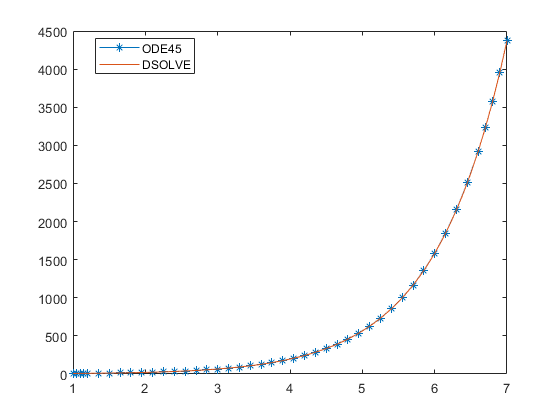

f = @(t, y) y + t^2-1;
y0 = 7;
tspan = [1 7];
[t, y] = ode45(f, tspan, y0);

plot(t, y, '*-');
hold on;
ysoln = dsolve('Dy = y + t^2 - 1', 'y(1)=7', 't');
x = 1:0.1:7;
yt = subs(ysoln, x);
yt = vpa(yt, 10);
xt = x;
plot(xt, yt);
hold off;
legend('ODE45', 'DSOLVE', 'Location', 'best');

tspan = 0:0.2:1;
y0 = [1, 0];
f = @(t, y) [y(2); t^2*y(2) + 2*t*y(1) + 1];
[t, y] = ode45(f, tspan, y0);
for i = 1:length(tspan)
    fprintf('y(%f) = %f\n', t(i), y(i, 1));
end

y(0.000000) = 1.000000
y(0.200000) = 1.022702
y(0.400000) = 1.102595
y(0.600000) = 1.262645
y(0.800000) = 1.541062
y(1.000000) = 2.009335


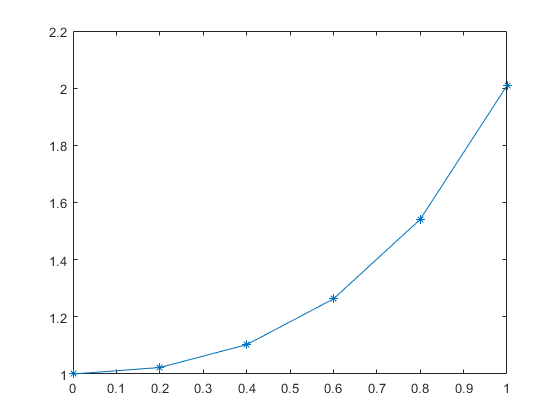

plot(t, y(:,1), '*-');

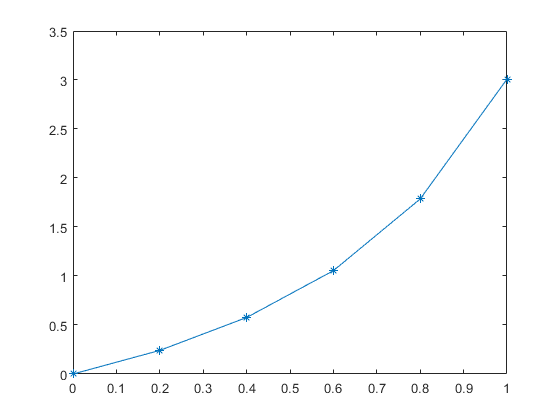

plot(t, y(:,2), '*-');

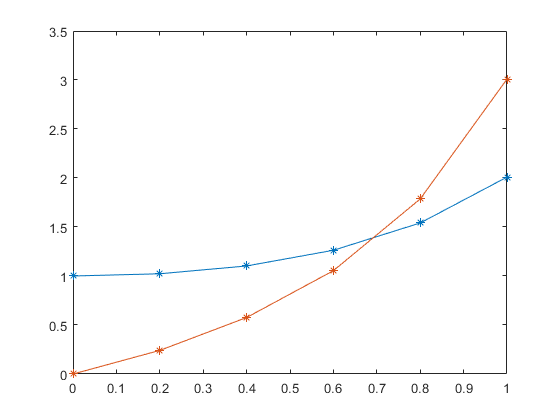

plot(t, y, '*-');

for i = 1:length(tspan)
    fprintf('y(%f) = %f\n', t(i), y(i, 2));
end

y(0.000000) = 0.000000
y(0.200000) = 0.240908
y(0.400000) = 0.576415
y(0.600000) = 1.054552
y(0.800000) = 1.786279
y(1.000000) = 3.009335


plot(t, y(:,2), '*-');

for i = 1:length(tspan)
    fprintf('y(%f) = %f\n', t(i), y(i, 1));
end

y(0.000000) = 1.000000
y(0.200000) = 1.022702
y(0.400000) = 1.102595
y(0.600000) = 1.262645
y(0.800000) = 1.541062
y(1.000000) = 2.009335


plot(t, y(:,1), '*-');